map = cell2mat(struct2cell(load("multilayerMap.mat")));
[startPoint, stopPoint] = startStopGenerator(map(:,:,1))

startPoint =    386   130


stopPoint =    119   239


% startPoint = [startPoint(2), startPoint(1)]
% stopPoint = [stopPoint(2), stopPoint(1)]
map(startPoint(1), startPoint(2))

ans = 1

map(stopPoint(1), stopPoint(2))

ans = 1

sum(map(:,:,1),"all")

ans = 17863

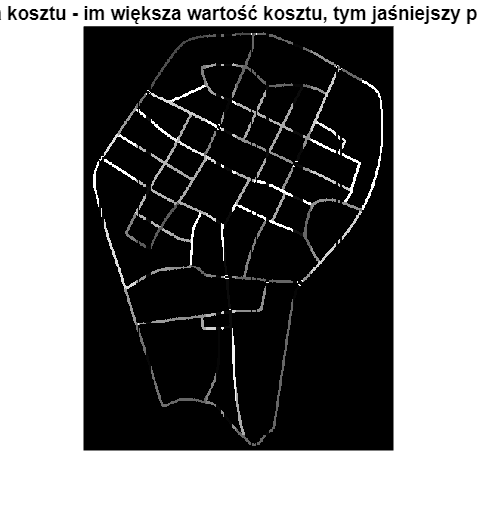


cost_map = map(:,:,1).*(map(:,:,2).*map(:,:,3) + map(:,:,4));
cost_map = (cost_map./max(cost_map).*255);
imshow(cost_map, [0, 255])
title("Mapa kosztu - im większa wartość kosztu, tym jaśniejszy piksel.")

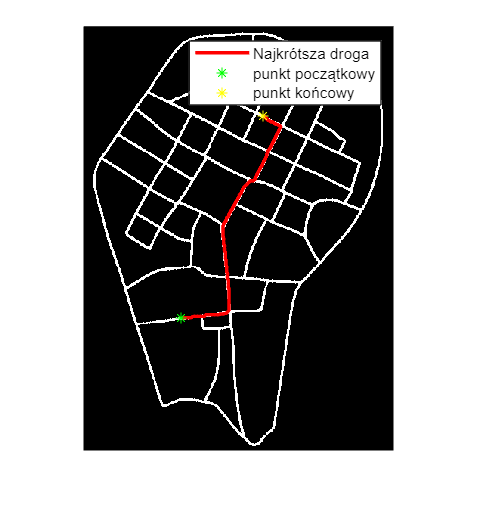

path = task_1(map, startPoint, stopPoint);
figure();
imshow(map(:,:,1))
hold on
plot(path(2:end, 2), path(2:end, 1), 'r', 'LineWidth', 2)

scatter(startPoint(2),startPoint(1), 'g*')
scatter(stopPoint (2),stopPoint(1), 'y*')
legend(["Najkrótsza droga","punkt początkowy","punkt końcowy"])
hold off